%% Parameter und Grundeinstellungen
phi = 48; % Geografische Breitengrad Muc
specific_days = [80, 172, 266, 355]; % 21. März, 21. Juni, 21. September, 21. Dezember
tage = 1:365; % Alle Tage des Jahres
P_max = 200; % Maximale Leistung der Solaranlage in W/m²(1m² groß?)

%% Berechnung der Taglängen
taglaengen = zeros(size(tage));

for i = 1:length(tage)
    delta = berechne_deklination(tage(i));
    try
        [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
        taglaengen(i) = sonnenuntergang - sonnenaufgang;
    catch
        taglaengen(i) = 0; % Keine Sonne (z. B. Polarnächte)
    end
end

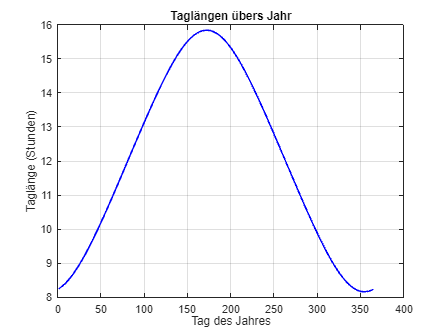

% Plot der Taglängen übers Jahr
figure;
plot(tage, taglaengen, 'b', 'LineWidth', 1.5);
title('Taglängen übers Jahr');
xlabel('Tag des Jahres');
ylabel('Taglänge (Stunden)');
grid on;


%% Berechnung der Energie für horizontale Solaranlage
E_horizontal_spezifisch = zeros(size(specific_days));
E_horizontal_gesamt = 0;

for doy = 1:365
    try
        % Berechnung der täglichen Energie für die horizontale Anlage
        E_tag = berechne_tagesenergie(doy, 0, 0, phi, P_max, false); % Neigung = 0°, Azimut = 0° (egal)
        E_horizontal_gesamt = E_horizontal_gesamt + E_tag;

        % Spezifische Tage speichern
        if ismember(doy, specific_days)
            E_horizontal_spezifisch(specific_days == doy) = E_tag;
        end
    catch
        % Fehler abfangen (z. B. keine Sonnenzeiten)
    end
end


%% Berechnung der Energie für vertikal (Süden ausgerichtet)
E_vertikal_spezifisch = zeros(size(specific_days));
E_vertikal_gesamt = 0;

for doy = 1:365
    try
        % Berechnung der täglichen Energie für die vertikale Anlage
        E_tag = berechne_tagesenergie(doy, 90, 0, phi, P_max, false); % Neigung = 90°, Azimut = 0° (Süden)
        E_vertikal_gesamt = E_vertikal_gesamt + E_tag;

        % Spezifische Tage speichern
        if ismember(doy, specific_days)
            E_vertikal_spezifisch(specific_days == doy) = E_tag;
        end
    catch
        % Fehler abfangen (z. B. keine Sonnenzeiten)
    end
end


%% Ergebnisse anzeigen
% Spezifische Tage und Energie (horizontal und vertikal)
tage_labels = {'21. März', '21. Juni', '21. September', '21. Dezember'};
energie_tabelle = table(...
    tage_labels', ...
    E_horizontal_spezifisch', ...
    E_vertikal_spezifisch', ...
    'VariableNames', {'Datum', 'Energie_Horizontal (Wh)', 'Energie_Vertikal (Wh)'});

% Tabelle anzeigen
disp('Energie an spezifischen Tagen:');

Energie an spezifischen Tagen:


disp(energie_tabelle);

          Datum          Energie_Horizontal (Wh)    Energie_Vertikal (Wh)
    _________________    _______________________    _____________________

    {'21. März'     }            1007.5                         0        
    {'21. Juni'     }            1755.5                    416.42        
    {'21. September'}            988.72                         0        
    {'21. Dezember' }            338.41                         0        




disp('Gesamte Jahresenergie:');

Gesamte Jahresenergie:


disp(['Horizontale Anlage: ', num2str(E_horizontal_gesamt), ' Wh']);

Horizontale Anlage: 376901.0452 Wh


disp(['Vertikale Anlage: ', num2str(E_vertikal_gesamt), ' Wh']);

Vertikale Anlage: 37567.5662 Wh



% Optimierung der Ausrichtung
beta_range = 0:5:90; % Neigungswinkel von 0° bis 90°
gamma_range = -180:10:180; % Azimutwinkel von -180° bis +180°

% Ergebnisse initialisieren
optimal_spezifisch = struct('beta', [], 'gamma', [], 'energie', []);
E_optimal_gesamt = 0;
beta_optimal_jahr = 0;
gamma_optimal_jahr = 0;

%% Berechnung für spezifische Tage
optimal_spezifisch = struct('beta', [], 'gamma', [], 'energie', []);
for d = 1:length(specific_days)
    doy = specific_days(d);
    E_best = 0;
    beta_best = 0;
    gamma_best = 0;

    for beta = beta_range
        for gamma = gamma_range
            % Energieberechnung mit der ausgelagerten Funktion
            try
                E_tag = berechne_tagesenergie(doy, beta, gamma, phi, P_max, false); % Fixe Ausrichtung
                if E_tag > E_best
                    E_best = E_tag;
                    beta_best = beta;
                    gamma_best = gamma;
                end
            catch
                % Fehler abfangen (z. B. keine Sonnenzeiten)
                continue;
            end
        end
    end

    % Speichern der optimalen Werte für den spezifischen Tag
    optimal_spezifisch(d).beta = beta_best;
    optimal_spezifisch(d).gamma = gamma_best;
    optimal_spezifisch(d).energie = E_best;
end



%% Berechnung der optimalen Ausrichtung übers Jahr
for beta = beta_range
    for gamma = gamma_range
        E_total = 0; % Speichert die Energie für eine bestimmte Kombination von Beta und Gamma

        for doy = 1:365
            try
                % Berechnung der täglichen Energie mit der ausgelagerten Funktion
                E_tag = berechne_tagesenergie(doy, beta, gamma, phi, P_max, false); % Fixe Ausrichtung
                E_total = E_total + E_tag; % Aufsummieren der Energie über das Jahr
            catch
                % Fehler abfangen (z. B. keine Sonnenzeiten)
                continue;
            end
        end

        % Aktualisierung der optimalen Werte, wenn die Energie größer ist
        if E_total > E_optimal_gesamt
            E_optimal_gesamt = E_total;
            beta_optimal_jahr = beta;
            gamma_optimal_jahr = gamma;
        end
    end
end

verbesserungsfaktor = E_optimal_gesamt / E_horizontal_gesamt;

%% Ergebnisse anzeigen
tage_labels = {'21. März', '21. Juni', '21. September', '21. Dezember'};
energie_optimal_tabelle = table(...
    tage_labels', ...
    [optimal_spezifisch(:).beta]', ...
    [optimal_spezifisch(:).gamma]', ...
    [optimal_spezifisch(:).energie]', ...
    'VariableNames', {'Datum', 'Beta (°)', 'Gamma (°)', 'Energie (Wh)'});

disp('Optimale Ausrichtung für spezifische Tage:');

Optimale Ausrichtung für spezifische Tage:


disp(energie_optimal_tabelle);

          Datum          Beta (°)    Gamma (°)    Energie (Wh)
    _________________    ________    _________    ____________

    {'21. März'     }       60          130          2147.4   
    {'21. Juni'     }       50           90          2719.6   
    {'21. September'}       60          130          2135.2   
    {'21. Dezember' }       80          150          1565.5   



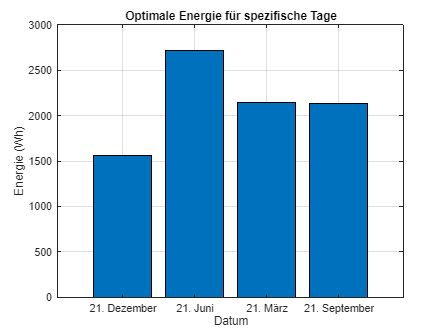


% Plot der Ergebnisse
figure;
bar(categorical(tage_labels), [optimal_spezifisch(:).energie]');
title('Optimale Energie für spezifische Tage');
xlabel('Datum');
ylabel('Energie (Wh)');
grid on;



fprintf('\nOptimale Ausrichtung für das gesamte Jahr:\n');


Optimale Ausrichtung für das gesamte Jahr:


fprintf('Beta = %.1f°, Gamma = %.1f°, Energie = %.2f Wh\n', beta_optimal_jahr, gamma_optimal_jahr, E_optimal_gesamt);

Beta = 60.0°, Gamma = 120.0°, Energie = 735576.51 Wh



fprintf('\nVerbesserungsfaktor im Vergleich zur horizontalen Anlage: %.2f\n', verbesserungsfaktor);


Verbesserungsfaktor im Vergleich zur horizontalen Anlage: 1.95


Folgender Code-Abschnitt beinhaltet die Nachführung der Anlage zur Sonne hin und die Energiegewinnung. Zudem wird die gewonnene Energie mit derjenigen Verglichen, sollte die Anlage sobald die Sonne scheint, die volle Energieleistung von 200 W/m² erreichen.        

% Anlage wird nachgeführt (Azimut variabel, Neigungswinkel fix 60°)
E_nachgefuehrt_gesamt = 0; % Energie nachgeführte Anlage
E_theoretisch_gesamt = 0; % Maximale theoretische Energie
beta_fix = 60; % Fixer Neigungswinkel

Nun wird für die Tage innerhalb eines Jahres die Energie berechnet, an welchen die Sonne scheint und die Anlage Energie abwirft. Hierfür wird vorab erneut die Länge des Tages berechnet, welche für die Kalkulation der theoretisch maximalen Energie  wichtig ist. Hier wird einfach die maximal mögliche Leistung mit den Sonnentagen multipliziert. Anschließend wird innerhalb von Sonnenauf- und Sonnenuntergang ein Array erstellt, in welchem die Leistung von regelmäßigen Zeitschritten gespeichert werden. 

Anschließend wird die Energie der Anlage berechnet, die produziert wird, wenn sich diese kontinuierlich zur Sonne hin ausrichtet. Hierbei wird die Funktion "berechne_tagesenergie"  aufgerufen, der optimale Neigungswinkel von 60° und ein variabler Azimut-Winkel übergeben.

for doy = 1:365
    delta = berechne_deklination(doy);
    try
        % Berechnung von Sonnenaufgang und Sonnenuntergang
        [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
        tageslaenge = sonnenuntergang - sonnenaufgang;

        % Theoretische maximale Energie (100%)
        if tageslaenge > 0
            E_tag_theoretisch = P_max * tageslaenge;
            E_theoretisch_gesamt = E_theoretisch_gesamt + E_tag_theoretisch;

            % Berechnung der Energie der nachgeführten Anlage
            E_tag_nachgefuehrt = berechne_tagesenergie(doy, beta_fix, 0, phi, P_max, true); % true: Azimut variabel
            E_nachgefuehrt_gesamt = E_nachgefuehrt_gesamt + E_tag_nachgefuehrt;
        end
    catch
        % Kein Sonnenaufgang oder Sonnenuntergang → keine Energie an diesem Tag
    end
end

Nun können berechnete Energie-Werte mit den vorherigen Ausrichtungs-Varianten verglichen werden. Hier zeigt sich, dass der Verbesserungsfaktor zur reinen horizontalen Anlage bei 2.21 und zur optimierten Anlage von davor bei 1.13 liegt. Hinsichtlich des bestmöglichen Ergebnises, liegt die Energiegewinnung für ein Nachführen der PV-Anlage bei rund 95%. 

% Vergleich mit der theoretischen maximalen Energie
prozentuale_energie_nachgefuehrt = (E_nachgefuehrt_gesamt / E_theoretisch_gesamt) * 100;
verbesserungsfaktor_nachgefuehrt_hor = E_nachgefuehrt_gesamt / E_horizontal_gesamt;
verbesserungsfaktor_nachgefuehrt_opt = E_nachgefuehrt_gesamt / E_optimal_gesamt;


disp('Gesamte Jahresenergie:');

Gesamte Jahresenergie:


disp(['Theoretisch maximale Energie (100%): ', num2str(E_theoretisch_gesamt), ' Wh']);

Theoretisch maximale Energie (100%): 876000 Wh


disp(['Tatsächliche Energie der nachgeführten Anlage: ', num2str(E_nachgefuehrt_gesamt), ' Wh']);

Tatsächliche Energie der nachgeführten Anlage: 834772.7016 Wh


fprintf('\nProzentuale Energie der nachgeführten Anlage: %.2f%%\n', prozentuale_energie_nachgefuehrt);


Prozentuale Energie der nachgeführten Anlage: 95.29%


fprintf('\nVerbesserungsfaktor im Vergleich zur horizontalen Anlage: %.2f', verbesserungsfaktor_nachgefuehrt_hor);


Verbesserungsfaktor im Vergleich zur horizontalen Anlage: 2.21

fprintf('\nVerbesserungsfaktor im Vergleich zur optimierten Anlage: %.2f', verbesserungsfaktor_nachgefuehrt_opt);


Verbesserungsfaktor im Vergleich zur optimierten Anlage: 1.13

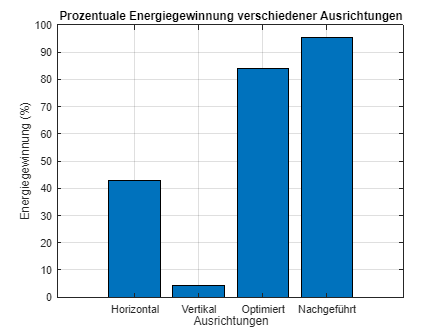

% Balkendiagramm der Energiegewinnung
prozentuale_energie_horizontal = (E_horizontal_gesamt / E_theoretisch_gesamt) * 100;
prozentuale_energie_vertikal = (E_vertikal_gesamt / E_theoretisch_gesamt) * 100;
prozentuale_energie_optimiert = (E_optimal_gesamt / E_theoretisch_gesamt) * 100;

% Daten für das Balkendiagramm
x_labels = {'Horizontal', 'Vertikal', 'Optimiert', 'Nachgeführt'}; % Kategorien auf der X-Achse
y_values = [prozentuale_energie_horizontal, prozentuale_energie_vertikal, prozentuale_energie_optimiert, prozentuale_energie_nachgefuehrt]; % Prozentwerte

% Erstellen des Balkendiagramms
figure; % Neue Figur öffnen
bar(y_values); % Balkendiagramm erstellen
ylim([0, 100]); % Y-Achse auf 0 bis 100 Prozent begrenzen

% Achsentitel und Beschriftungen
set(gca, 'XTickLabel', x_labels); % X-Achsen-Beschriftungen
title('Prozentuale Energiegewinnung verschiedener Ausrichtungen');
ylabel('Energiegewinnung (%)'); % Y-Achsen-Beschriftung
xlabel('Ausrichtungen'); % X-Achsen-Beschriftung
grid on; % Gitter hinzufügen

function delta = berechne_deklination(doy)
    delta = 23.45 * sind((360 / 365) * (doy + 284));
end

% Berechnung des Stundenwinkels
function H = berechne_stundenwinkel(t)
    H = 15 * (t - 12);
end

% Berechnung des Höhenwinkels
function alpha = berechne_hoehenwinkel(phi, delta, H)
    alpha = asind(sind(phi) * sind(delta) + cosd(phi) * cosd(delta) * cosd(H));
end

% Berechnung des Azimuts
function azimut = berechne_azimut(phi, delta, alpha)
    azimut = acosd((sind(delta) - sind(alpha) * sind(phi)) / (cosd(alpha) * cosd(phi)));
end

% Berechnung von Sonnenaufgang und Sonnenuntergang
function [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta)
    sonnenaufgang = fzero(@(t) sind(phi) * sind(delta) + cosd(phi) * cosd(delta) * cosd(15 * (t - 12)), [0, 12]);
    sonnenuntergang = fzero(@(t) sind(phi) * sind(delta) + cosd(phi) * cosd(delta) * cosd(15 * (t - 12)), [12, 24]);
end

function E_tag = berechne_tagesenergie(doy, beta, gamma, phi, P_max, azimut_variabel)
    % Berechnung der Energie für einen bestimmten Tag
    % Parameter:
    % - doy: Tag des Jahres
    % - beta: Neigungswinkel der Anlage
    % - gamma: Azimutwinkel der Anlage (bei azimut_variabel ignoriert)
    % - phi: Breitengrad
    % - P_max: Maximale Leistung der Anlage
    % - azimut_variabel: Boolean (true für nachgeführte Anlage, false für fixe Ausrichtung)

    delta = berechne_deklination(doy);
    [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
    zeiten = linspace(sonnenaufgang, sonnenuntergang, 20);
    P_t = zeros(size(zeiten));

    for i = 1:length(zeiten)
        alpha = berechne_hoehenwinkel(phi, delta, berechne_stundenwinkel(zeiten(i)));
        azimut_sonne = berechne_azimut(phi, delta, alpha);

        if azimut_variabel
            % Bei einer nachgeführten Anlage ist der Azimutwinkel der Anlage gleich dem der Sonne
            gamma = azimut_sonne;
        end

        % Vektorberechnung
        vektor_sonne = [cosd(alpha) * sind(azimut_sonne), cosd(alpha) * cosd(azimut_sonne), sind(alpha)];
        vektor_anlage = [sind(beta) * sind(gamma), sind(beta) * cosd(gamma), cosd(beta)];

        % Punktprodukt
        cos_theta = max(0, dot(vektor_sonne, vektor_anlage));
        P_t(i) = max(0, P_max * cos_theta);
    end

    % Numerische Integration über den Tag
    E_tag = trapz(zeiten, P_t);
end